# Tutorial 5 - Simulate CC-CV Cycling

## Introduction

In this tutorial, we will use a P2D model to simulate CC-CV cycling. After completing this tutorial, you should have a working knowledge of:

- How to define and modify cycling protocols in BattMo

We'll use the same model from Tutorial 1.

jsonstruct = parseBattmoJson('Examples/jsondatafiles/sample_input.json');

Parameters are defined in the JSON parameter file and parsed into the MATLAB structure. Once the JSON file has been read into MATLAB as a jsonstruct, its properties can be modified programmatically.

## Explore the Control Definition

Let's begin by reviewing the control protocol in BattMo, with the command:

disp(jsonstruct.Control)

         controlPolicy: 'CCDischarge'
                 DRate: 1
    lowerCutoffVoltage: 3
    upperCutoffVoltage: 4.1000
             dIdtLimit: 0.0100
             dEdtLimit: 0.0100
            rampupTime: 0.1000



We see that the default control protocol is set to a constant current (galvanostatic) discharge. To change to a CC-CV cycling protocol, we can use the command:

cccv_control_protocol = parseBattmoJson('cccv_control.json');
jsonstruct_modified = mergeJsonStructs({cccv_control_protocol, jsonstruct});

mergeJsonStructs: Parameter Control.controlPolicy is assigned twice with different values. Value from first jsonstruct is used.
mergeJsonStructs: Parameter Control.lowerCutoffVoltage is assigned twice with different values. Value from first jsonstruct is used.
mergeJsonStructs: Parameter Control.upperCutoffVoltage is assigned twice with different values. Value from first jsonstruct is used.
mergeJsonStructs: Parameter Control.dIdtLimit is assigned twice with different values. Value from first jsonstruct is used.
mergeJsonStructs: Parameter Control.dEdtLimit is assigned twice with different values. Value from first jsonstruct is used.


Now we can explore the modified control protocol definition with the command:

disp(jsonstruct_modified.Control)

         controlPolicy: 'CCCV'
        initialControl: 'discharging'
        numberOfCycles: 5
                 CRate: 0.5000
                 DRate: 1
    lowerCutoffVoltage: 2.8000
    upperCutoffVoltage: 4.2000
             dIdtLimit: 2.0000e-06
             dEdtLimit: 2.0000e-06
            rampupTime: 0.1000



Let's run the simulation and plot the cell voltage curve.

% run the simulation
output = runBatteryJson(jsonstruct_modified);

Solving timestep 001/135:          -> 15 Seconds, 625 Milliseconds
| It # | ctrl_EIequation (cell) | ctrl_controlEquation (cell) | ne_co_am_sd_massCons (cell) | ne_co_am_sd_solidDiffusionEq (cell) | ne_co_chargeCons (cell) | pe_co_am_sd_massCons (cell) | pe_co_am_sd_solidDiffusionEq (cell) | pe_co_chargeCons (cell) | elyte_chargeCons (cell) | elyte_massCons (cell) |
|    1 | 3.01e-03          

|    3 |*6.82e-13               |*0.00e+00                    | 6.47e-01                    | 6.47e-01                            | 5.16e-01                | 8.49e+17                    | 8.49e+17                            | 6.07e+17                | 7.63e+17                | 7.63e+17              |
|    4 |*6.82e-13               |*0.00e+00                    | 1.28e+01                    | 1.51e+03                            | 1.02e+01                | 5.24e+25                    | 5.24e+25                            | 3.75e+25                | NaN                     | NaN                   |
Solver failure after 3 iterations for timestep of length 500 Seconds. Cutting timestep.
Failure reason: Linear system rhs have infinite entries
Cutting timestep.

|    3 |*1.60e-12               |*0.00e+00                    | 6.48e-01                    | 6.48e-01                            | 5.17e-01                | 3.06e+18                    | 3.06e+18                            | 2.18e+18                | 2.75e+18                | 2.75e+18              |
|    4 |*6.82e-13               |*0.00e+00                    | 4.26e+00                    | 4.26e+00                            | 3.40e+00                | 3.34e+20                    | 3.34e+20                            | 2.39e+20                | NaN                     | NaN                   |
Solver failure after 3 iterations for timestep of length 500 Seconds. Cutting timestep.
Failure reason: Linear system rhs have infinite entries
Cutting timestep.

|    3 |*1.60e-12               |*0.00e+00                    | 6.48e-01                    | 6.48e-01                            | 5.16e-01                | 1.32e+18                    | 1.32e+18                            | 9.46e+17                | 1.19e+18                | 1.19e+18              |
|    4 |*6.82e-13               |*0.00e+00                    | NaN                         | NaN                                 | NaN                     | NaN                         | NaN                                 | NaN                     | NaN                     | NaN                   |
Solver failure after 3 iterations for timestep of length 500 Seconds. Cutting timestep.
Failure reason: Linear system rhs have infinite entries
Cutting timestep.

|    3 |*1.60e-12               |*0.00e+00                    | 6.50e-01                    | 6.50e-01                            | 5.18e-01                | 2.06e+19                    | 2.06e+19                            | 1.47e+19                | 1.85e+19                | 1.85e+19              |
|    4 |*4.60e-13               |*0.00e+00                    | 2.44e+00                    | 2.44e+00                            | 1.95e+00                | 8.40e+70                    | 8.40e+70                            | 6.01e+70                | NaN                     | NaN                   |
Solver failure after 3 iterations for timestep of length 500 Seconds. Cutting timestep.
Failure reason: Linear system rhs have infinite entries
Cutting timestep.

|    3 |*6.82e-13               |*0.00e+00                    | 6.48e-01                    | 6.48e-01                            | 5.17e-01                | 2.48e+18                    | 2.48e+18                            | 1.77e+18                | 2.23e+18                | 2.23e+18              |
|    4 |*6.82e-13               |*0.00e+00                    | 5.04e-01                    | 5.04e-01                            | 4.02e-01                | 5.67e+18                    | 5.67e+18                            | 4.06e+18                | NaN                     | NaN                   |
Solver failure after 3 iterations for timestep of length 500 Seconds. Cutting timestep.
Failure reason: Linear system rhs have infinite entries
Cutting timestep.

get the states

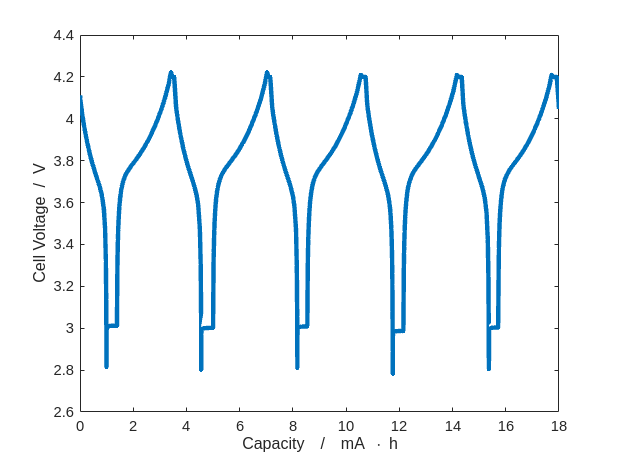

states = output.states;

% extract the time and voltage quantities
time = cellfun(@(state) state.time, states);
voltage = cellfun(@(state) state.('Control').E, states);
current = cellfun(@(state) state.('Control').I, states);

% calculate the capacity
capacity = time .* current;

% plot the discharge curve in the figure
plot(time/hour, voltage, '-', 'linewidth', 3)

% add plot annotations
xlabel('Capacity  /  mA \cdot h')
ylabel('Cell Voltage  /  V')

## Summary

In this tutorial, we explored how to modify material parameters in BattMo.